# Exercise 2 regbot

## Plot data from the log txt file

data = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\regbot_log_4.txt');
data = fillmissing(data, 'nearest');

data2 = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\regbot_log_4_2.txt');
data2 = fillmissing(data2, 'nearest');

data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\regbot_log_4_wd.txt');
data_wd = fillmissing(data_wd, 'nearest');

t = table2array(data(:,1));     % time stamps
u_L = table2array(data(:,8));   % left motor voltage
u_R = table2array(data(:,9));   % right motor voltage
v_L = table2array(data(:,10));  % left motor velocity 
v_R = table2array(data(:,11));  % right motor velocity
T_s = t(2) - t(1);              % compute sampling time

%{
t = table2array(data2(:,1));    
u_L = table2array(data2(:,2));   
u_R = table2array(data2(:,3));   
v_L = table2array(data2(:,4));  
v_R = table2array(data2(:,5)); 
T_s = t(2) - t(1);   
%}           

%Trim data
% Find the index where X becomes 3 for the first time

idx = find(u_L >= 4,1,'first');
idx = idx - 20

idx = 731

% Keep only the data after this index
u_L = u_L(idx:end); 
v_L = v_L(idx:end);
u_R = u_R(idx:end); 
v_R = v_R(idx:end);
% Do the same for the time vector
t = t(idx:end);                 
t = t - t(1);

vel = 1/2*(v_L + v_R);          % average wheel velocity
volt = 1/2*(u_L + u_R);         % average voltage

idd_L = iddata(v_L,u_L,T_s);    % Prepare left wheel data
idd_R = iddata(v_R,u_R,T_s);    % Prepare right wheel data
idd_A = iddata(vel,volt,T_s);    % Prepare average wheel data

G_wu_L = tfest(idd_L,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_L =
 
  From input "u1" to output "y1":
         327.9
  --------------------
  s^2 + 96.08 s + 1093
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_L".
Fit to estimation data: 81.48%                    
FPE: 0.0001974, MSE: 0.0001947                    


G_wu_R = tfest(idd_R,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_R =
 
  From input "u1" to output "y1":
        530.3
  ------------------
  s^2 + 122 s + 1636
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_R".
Fit to estimation data: 85.38%                    
FPE: 0.0001179, MSE: 0.0001163                    


G_wu_A = tfest(idd_A,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_A =
 
  From input "u1" to output "y1":
         368.9
  --------------------
  s^2 + 97.43 s + 1182
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_A".
Fit to estimation data: 83.75%                    
FPE: 0.0001484, MSE: 0.0001463                    


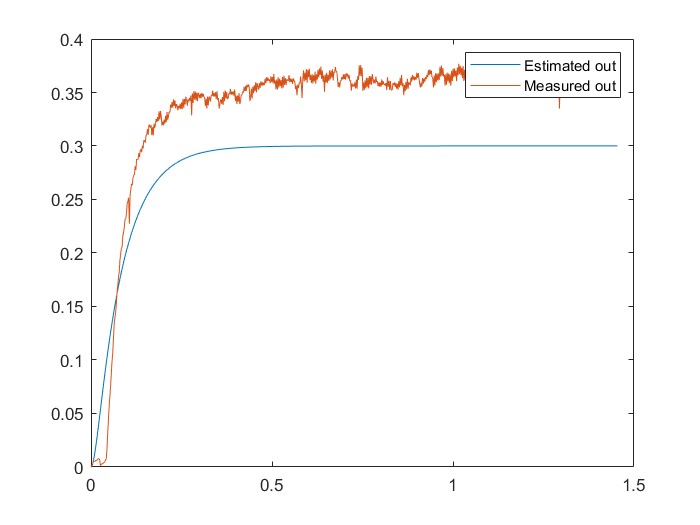

v_L_out = v_L - v_L(1);

[y_L,t_L] = step(G_wu_L,t(end));
plot(t_L,y_L);
hold on;
plot(t,v_L_out);
hold off;
legend('Estimated out','Measured out');

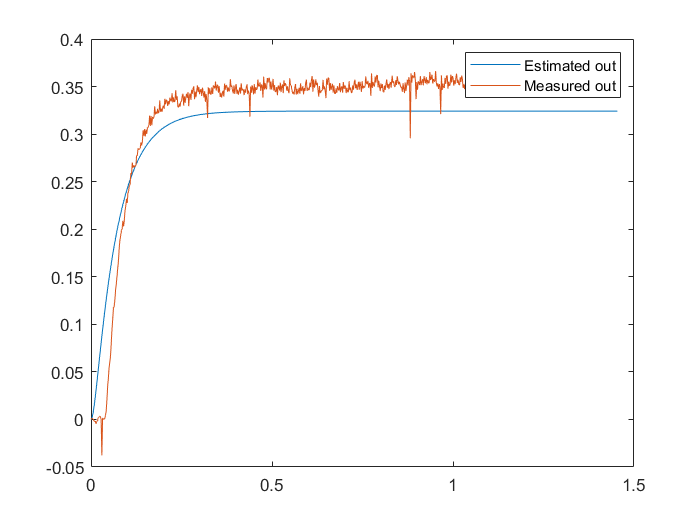


v_R_out = v_R - v_R(1);

[y_R,t_R] = step(G_wu_R,t(end));
plot(t_R,y_R);
hold on;
plot(t,v_R_out);
hold off;
legend('Estimated out','Measured out');

v_A_out = vel - vel(1)

v_A_out =          0
    0.0014
    0.0012
    0.0025
    0.0020
    0.0014
    0.0020
    0.0009
    0.0019
    0.0030


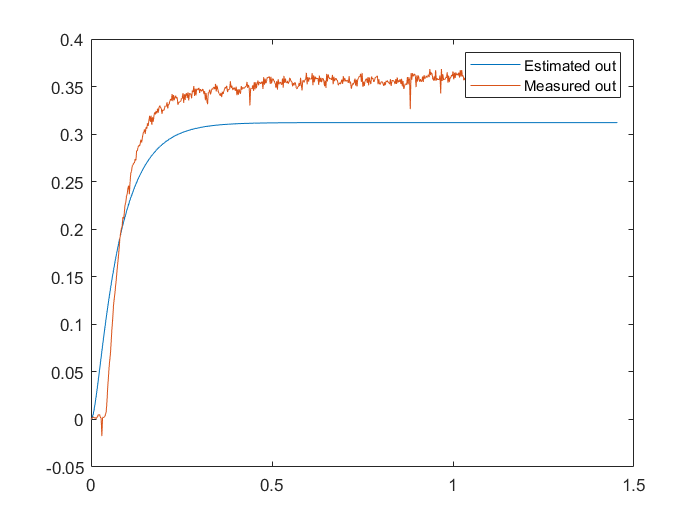


[y_A,t_A] = step(G_wu_A,t(end));
plot(t_A,y_A);
hold on;
plot(t,v_A_out);
hold off;
legend('Estimated out','Measured out');

t = table2array(data_wd(:,1))    % time stamps

t =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180


u_L = table2array(data_wd(:,8))   % left motor voltage

u_L =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


u_R = table2array(data_wd(:,9))  % right motor voltage

u_R =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


v_L = table2array(data_wd(:,10))  % left motor velocity 

v_L =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


v_R = table2array(data_wd(:,11))  % right motor velocity

v_R =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


T_s = t(2) - t(1)              % compute sampling time

T_s = 0.0020

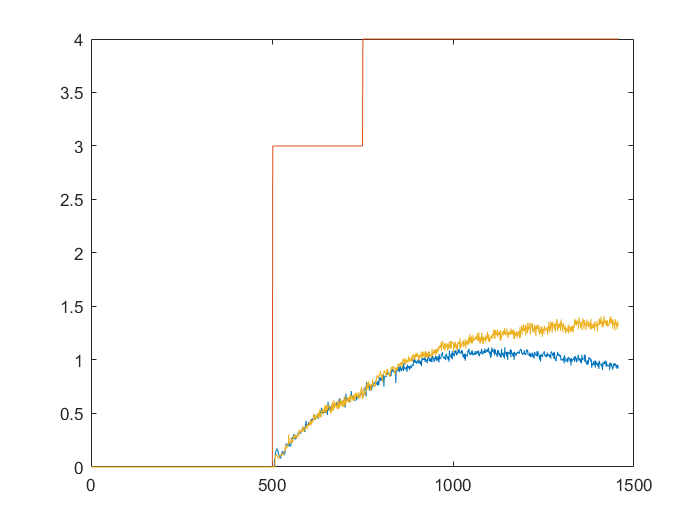


figure
plot(v_L)

hold on
plot(u_L)
plot(v_R)
hold off

idx = find(u_L >= 4,1,'first')

idx = 751

idx = idx - 20

idx = 731

t = t(idx:end);                 
t = t - t(1);

u_L = u_L(idx:end) 

u_L =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


v_L = v_L(idx:end)

v_L =     0.6677
    0.6670
    0.6595
    0.6243
    0.6564
    0.6555
    0.6648
    0.6420
    0.6624
    0.6447


u_R = u_R(idx:end)

u_R =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


v_R = v_R(idx:end)

v_R =     0.6961
    0.6510
    0.6785
    0.6911
    0.6722
    0.6543
    0.6804
    0.6402
    0.6621
    0.7004



vel = 1/2*(v_L + v_R)         % average wheel velocity

vel =     0.6819
    0.6590
    0.6690
    0.6577
    0.6643
    0.6549
    0.6726
    0.6411
    0.6623
    0.6725


volt = 1/2*(u_L + u_R)         % average voltage

volt =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3



idd_A = iddata(v_R,u_R,T_s)    % Prepare average wheel data

idd_A =

Time domain data set with 727 samples.
Sample time: 0.002 seconds             
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
   u1                                  
                                       


      
G_wu_A = tfest(idd_A,1,0) % Identify wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_A =
 
  From input "u1" to output "y1":
   0.7314
  ---------
  s + 2.126
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_A".
Fit to estimation data: 83.98%                    
FPE: 0.0009233, MSE: 0.0009157                    



v_A_out = vel - vel(1)

v_A_out =          0
   -0.0229
   -0.0129
   -0.0242
   -0.0176
   -0.0270
   -0.0093
   -0.0408
   -0.0196
   -0.0093



[y_A,t_A] = step(G_wu_A,t(end))

y_A =          0
    0.0105
    0.0207
    0.0305
    0.0401
    0.0494
    0.0583
    0.0671
    0.0755
    0.0837


t_A =          0
    0.0146
    0.0291
    0.0437
    0.0583
    0.0729
    0.0874
    0.1020
    0.1166
    0.1311


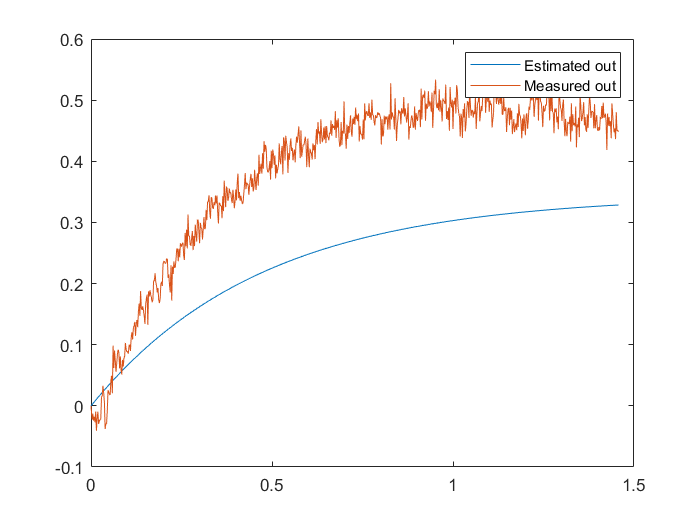

plot(t_A,y_A)
hold on;
plot(t,v_A_out)
hold off;
legend('Estimated out','Measured out')